Controller Synthesis for a DC motor using Lyapunov's criteria.

The equiment has the following specifications:

clear all; close all
R = 0.2;
L = 0.1;
J = 1;
B = [0.1;1];
Ka = 1;

First, we define the space-state equations of the DC motor:

% A_1 = [-R/L 0 0;Ka/J -B(1)/J 0; 0 0 1];
% A_2 = [-R/L 0 0;Ka/J -B(2)/J 0; 0 0 1];
A_1 = [-R/L 0;Ka/J -B(1)/J];
A_2 = [-R/L 0;Ka/J -B(2)/J];
% B = [1/L; 0; 0];
B = [1/L; 0];
C = [0 1];
D = 0;

Now, we implement the Controller Synthesis to the present study case:

[rowB colB] = size(B)

rowB = 2

colB = 1


Q = sdpvar(length(A_1));
Y = sdpvar(colB,rowB);

sdisplay(Q);
sdisplay(Y);

LMI1 = [(A_1*Q-B*Y)+(A_1*Q-B*Y)'<=0];
LMI2 = [(A_2*Q-B*Y)+(A_2*Q-B*Y)'<=0];
% LMI1 = [Q*A_1'+A_1*Q+Y'*B'+B*Y<=0];
% LMI2 = [Q*A_2'+A_2*Q+Y'*B'+B*Y<=0];
LMI3 = [Q>=0];

LMI = [LMI1,LMI2,LMI3];

optimize(LMI)

SeDuMi 1.3.5 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 5, order n = 7, dim = 13, blocks = 4
nnz(A) = 17 + 0, nnz(ADA) = 25, nnz(L) = 15
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            9.84E+02 0.000
  1 :   0.00E+00 2.00E+02 0.000 0.2032 0.9000 0.9000   1.00  1  0  1.7E+01
  2 :   0.00E+00 5.14E+00 0.000 0.0257 0.9900 0.9900   1.00  1  1  4.3E-01
  3 :   0.00E+00 5.09E-02 0.000 0.0099 0.9990 0.9990   1.00  1  1  4.2E-03
  4 :   0.00E+00 4.96E-04 0.000 0.0098 0.9990 0.9990   1.00  1  1  4.1E-05
  5 :   0.00E+00 4.84E-06 0.000 0.0097 0.9990 0.9990   1.00  1  1  4.0E-07
  6 :   0.00E+00 4.71E-08 0.000 0.0097 0.9990 0.9990   1.00  1  1  3.9E-09
  7 :   0.00E+00 4.60E-10 0.000 0.0097 0.9990 0.9990   1.00  1  1  3.9E-11

iter seconds digits       c*x               b*y
  7      0.5   Inf  0.0000000000e+00  0.0000000000e+00
|Ax-b| =   1.9e-11, [Ay-c]_+ =   0.0E+00, |x|=  1.4e-12, |y|=  1

ans = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.14.0.2206163 (R2023a)'
       yalmiptime: 1.2169
       solvertime: 0.6901
             info: 'Successfully solved (SeDuMi-1.3)'
          problem: 0



checkset(LMI)

 
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|          Constraint|   Primal residual|   Dual residual|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Matrix inequality|           0.54815|      4.5868e-13|
|   #2|   Matrix inequality|           0.97973|      3.6389e-13|
|   #3|   Matrix inequality|           0.55814|      2.9348e-13|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
| A primal-dual optimal solution would show non-negative residuals.|
| In practice, many solvers converge to slightly infeasible    |
| solutions, which may cause some residuals to be negative.    |
| It is up to the user to judge the importance and impact of   |
| slightly negative residuals (i.e. infeasibilities)           |
| https://yalmip.github.io/command/check/                      |
| https://yalmip.github.io/faq/solutionviolated/               |
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
 



Qs = value(Q);
Ys = value(Y);

K = Ys*inv(Qs);

e1 = eig(A_1-B*K)

e1 =   -0.4883 + 1.3774i
  -0.4883 - 1.3774i


e2 = eig(A_2-B*K)

e2 =   -0.9383 + 1.4298i
  -0.9383 - 1.4298i


Time analysis:

t = 0:0.1:20;
x = zeros(rowB,length(t));
x(:,1) = [0 1]';

Runge-Kutta 4th order method:

for i = 1:length(t)
    b(i) = 0.1+0.9*rand;
    Amf = [-R/L 0;Ka/J -b(i)/J];
    k1 = (Amf-B*K)*x(:,i);
    k2 = (Amf-B*K)*(x(:,i)+0.5*0.1*k1);
    k3 = (Amf-B*K)*(x(:,i)+0.5*0.1*k2);
    k4 = (Amf-B*K)*(x(:,i)+0.5*k3);
    x(:,i+1) = x(:,i)+(0.1/6)*(k1+2*(k2+k3)+k4);
end

Ymf = C*x;

Using its differential equation representation:

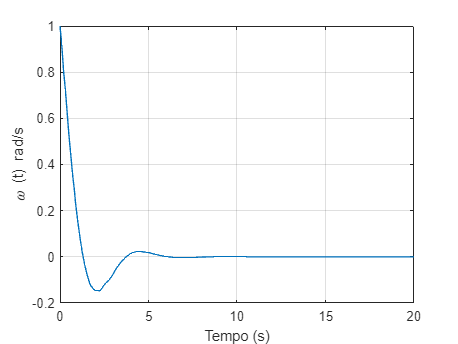

figure(1)
plot(t,Ymf(1:end-1))
xlabel('Tempo (s)')
ylabel('\omega (t) rad/s')
grid

Using its transfer function:

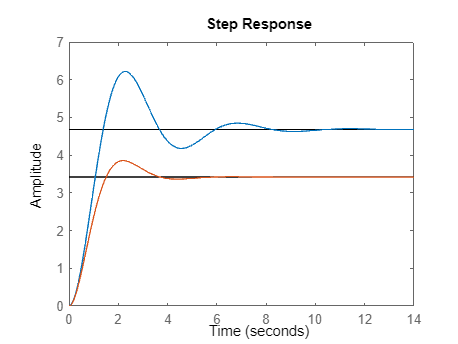

Gmf1 = ss(A_1-B*K,B,C-D*K,D);
step(Gmf1)
hold on
Gmf2 = ss(A_2-B*K,B,C-D*K,D);
step(Gmf2)
hold off